# CS283 Assignment 4

Enmao Diao, 2017/10/05

*Note: Matlab requires that all local functions in a live script appear at the end of the script. So, your code defining functions must appear at the very bottom of this file, after all other code that makes references to those functions. Also, each function definition must terminate with "end". More information is in the *[Matlab documentation](https://www.mathworks.com/help/matlab/matlab_prog/local-functions-in-scripts.html)*.*

# Question 1

(a)

We follow the algorithm listed in chapter 18. We know that affine camera can be written as 


$$\tilde \mathbf{x} = \mathbf{M}_{2x3}\tilde\mathbf{X}+\mathbf{t}_{2x1}$$


The projection of the (unknown) 3D centroid is the (known) 2D centroid of the projected points.


$$\langle\tilde \mathbf{x}\rangle = \mathbf{M}_{2x3}\langle\tilde\mathbf{X}\rangle+\mathbf{t}_{2x1}$$


and we can choose the world coordinate system such that $\langle\tilde\mathbf{X}\rangle = \mathbf{0}$ and thus $\mathbf{t}_{2x1}^i = \langle\tilde \mathbf{x}^i\rangle$

following the algorithm, we center the coordinates and then build data matrix $\mathbf{W}$. In the noiseless case, $\mathbf{W}$ should be rank 3. We therefore find the best rank 3 approximation by SVD factorization.

Then the matrices  are obtained from the first three columns of $\mathbf{U}$ multiplied by the singular values.  The world pointsared read from the first three

columns of $\mathbf{V}$  

The angles are not presented correctly because we only assume the affine camera and reconstruct to affine scale. Angles can only be correctly presented at least in the similarity scale. However, we do correctly present parallelism because of affine reconstruction.

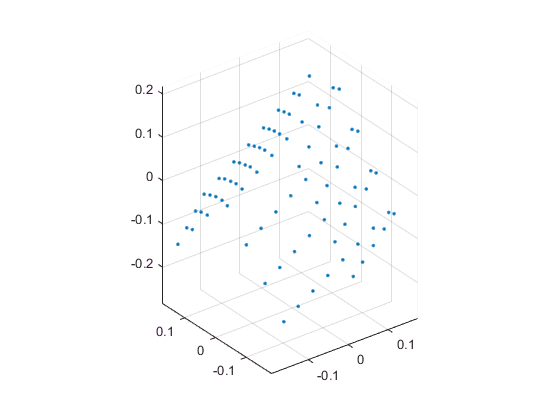

load('./data/corners.mat')
[M,T,X] = AffineFactorization(corners);
figure;
plot3(X(:,1),X(:,2),X(:,3),'.');
grid on;
axis equal;

(b)

We compute the RMS for x and y coordinates according to the given formula.

n = size(X,1);
m = size(T,2);
tmp_1 = 0;
for i = 1:m
    tmp_1 = tmp_1 + sum((corners(:,:,i)'-(M((i-1)*2+1:i*2,:)*X'+repmat(T(:,i),1,n))).^2,2);
end
rms_1 = sqrt(tmp_1/(m*n))

rms_1 =     0.6603
    1.2577


(c)

After optimize matrix $\mathbf{A}$, we compute homography $\mathbf{H}$and 


$$\mathbf{X}_{up} = \mathbf{HX}$$


we then scaled the results such that the average distance from a world point to the world origin is $\sqrt3$  


$$\mathbf{X}_{scaled} = \mathbf{TX}$$



$$\mathbf{M}_{scaled} = s^{-1}\mathbf{MA}$$


The RMS in (b) is exactly the same as in (c). This is because in (b) we have achieved affine scale reconstruction and it perserves ratio of volumes and centroid (linear combinations of vectors). If we scale the upgraded world coordinates to their centroid in such way, then $\mathbf{X}_{scaled}$ and $\mathbf{M}_{scaled}$ are actually another possible factorization of the data matrix $\mathbf{W}$in (a). Thus they all have the same RMS error.

[M_up,X_up] = Upgrade(M,X);


Solver stopped prematurely.

lsqnonlin stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1800 (the default value).



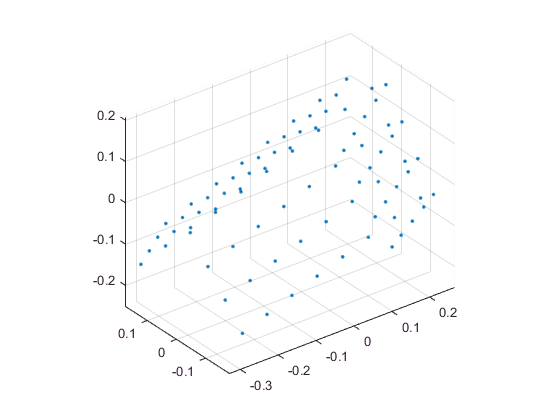

figure;
plot3(X_up(:,1),X_up(:,2),X_up(:,3),'.');
axis equal;
grid on;

tmp_2 = 0;
for i = 1:m
    tmp_2 = tmp_2 + sum((corners(:,:,i)'-(M_up((i-1)*2+1:i*2,:)*X_up'+repmat(T(:,i),1,n))).^2,2);
end
rms_2 = sqrt(tmp_2/(m*n))

rms_2 =     0.6603
    1.2577


# Question 2

.(a)

By definition, the spatial frequence is $\mathbf{w} = \sqrt{u^2 + v^2$, under $v$ equals to zero we have $\mathbf{w}_{max} =\max(|u|)$

Since $u = 0,1,\dots,M-1$, thus the maximum spatial frequence attained when $u = M-1$

(b) 

For 2d fourier transform


$$F(u,v) = \sum_{x=0}^{M-1}\sum_{y=0}^{N-1}f(x,y)e^{-j2π(ux/M+vy/N)}$$



$$\mathcal {F}\{f(x,y)(−1)^{x+y}\} = \sum_{x=0}^{M-1}\sum_{y=0}^{N-1}f(x,y)(−1)^{x+y}e^{-j2π(ux/M+vy/N)}$$



$$= \sum_{x=0}^{M-1}\sum_{y=0}^{N-1}f(x,y)e^{j\pi(x+y)}e^{-j2\pi(ux/M+vy/N)}$$



$$= \sum_{x=0}^{M-1}\sum_{y=0}^{N-1}f(x,y)e^{-j2\pi((u-M/2)x/M+(v-N/2)y/N)}$$



$$=F(u-M/2,v-N/2)$$


# Question 3

(a)

We manually identify the noise and their correspoding indcies as $[193,193;321,193;193,321;321,321]$, and the center of image is


$$(N/2+1,M/2+1)=(257,257)$$


thus the radial center of the frequency band, the distance between noisy coordiantes and center of image, is about 


$$\sqrt{(2*(321-257)^2)} \simeq 91$$


we choose $w = 10$

We set the center of image, the DC component, to zero in order show an more informative image.

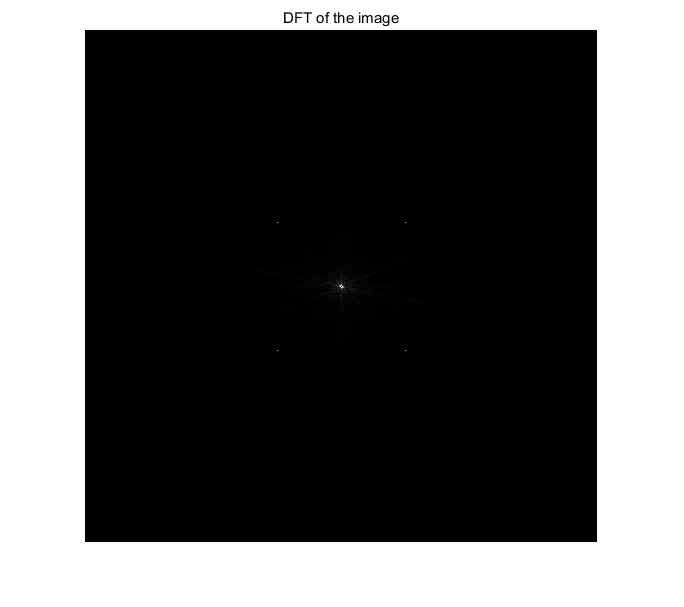

im = imread('./data/Cameraman_PeriodicNoise.tif');
[N,M] = size(im);
[X,Y] = meshgrid(1:M,1:N);
centered_im = (-1).^(X+Y).*double(im);
F = fft2(centered_im);
tmp_F = F;
tmp_F(M/2+1,N/2+1)=0;
mag_F = abs(tmp_F);
figure;
imshow(mag_F,[])
title('DFT of the image')

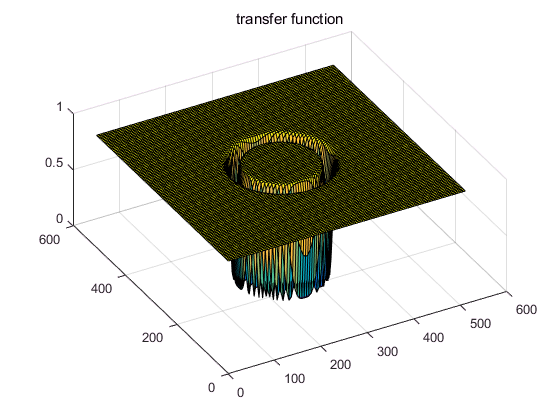

D0 = 91;
w = 10;
D = @(u,v) ((u-(M/2+1)).^2 + (v-(N/2+1)).^2).^(1/2);
H = @(u,v,D0,w) 1 - exp(-1/2*((D(u,v).^2-D0^2)./(w*D(u,v))).^2);
[U,V] = meshgrid(1:size(F,1),1:size(F,2));
Z = H(U,V,D0,w);
[U_t,V_t] = meshgrid(1:5:size(F,1),1:5:size(F,2));
Z_t = H(U_t,V_t,D0,w);
figure;
surf(U_t,V_t,Z_t)
title('transfer function')
view([-30 55])

(b)

We follow the hint to center and decenter the data. The result is shown in the figure.

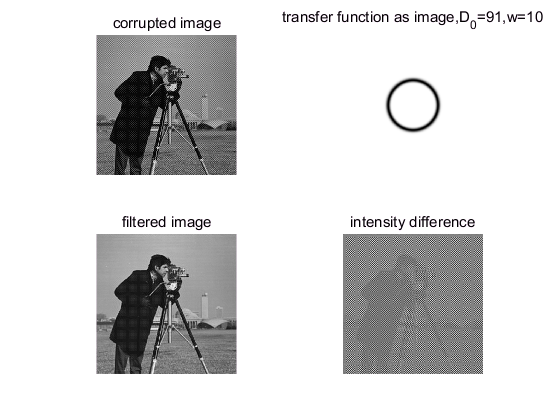

F_p = F.*Z;
I = ifft2(F_p);
decentered_I =(-1).^(X+Y).*real(I);
A = mat2gray(decentered_I);
B = mat2gray(im);
diff_inten = A-B;
figure;
subplot(2,2,1)
imshow(im,[]);
title('corrupted image')
subplot(2,2,2)
imshow(Z,[]);
title(sprintf('transfer function as image,D_0=%d,w=%d',D0,w))
subplot(2,2,3)
imshow(A,[]);
title('filtered image')
subplot(2,2,4)
imshow(diff_inten,[]);
title('intensity difference')

(c)

By definition, the impulse response of a filter is the output we get when we use a delta function as its input. A image with d(x,y) that has an impulse at (x=0,y=0), all other places are zero, we can compute its fourier transform and apply our filter to get a filtered image. The filtered image is our frequence response of filter. In fact, the fourier transform of delta function is all ones. Therefore, the impulse response of a filter is equivalent to the IFFT of the frequency reponse of the filter. To show the impulse response as image, we manually set d(0,0) = 0 since it always equal to 1 and it may be too large to show an informative image. It is similar to the high DC component case.

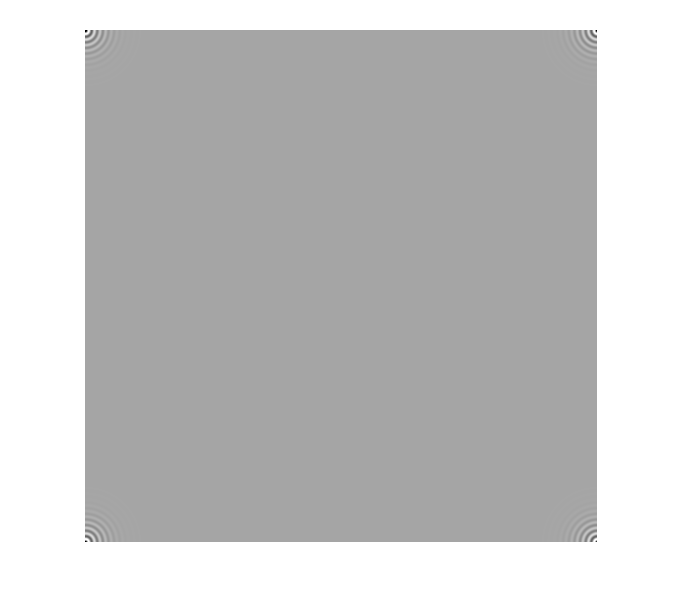

delta = zeros(N,M);
delta(1,1) = 1;
centered_delta = (-1).^(X+Y).*double(delta);
F_delta = fft2(centered_delta);
F_delta_p = F_delta.*Z;
I_delta = ifft2(F_delta_p);
decentered_I_delta =(-1).^(X+Y).*real(I_delta);
ir = mat2gray(decentered_I_delta);
tmp_ir = ir;
tmp_ir(1,1) = 0;
figure;
imshow(tmp_ir,[]);

(d)

Changing the bandwidth $w$ indeed creates noticeably differences. As the bandwidth increases, more and more frequencies are attenuated, and thus the intensity of image is decreases. The instensity of  the pixels of the coat of the camera man are stable (mostly black), and thus the periodic noises superimposed on the camera man must correspond to lower frequencies. By attenuating those frequencies, the intensity difference of the camera man between the correupted and filter figures apparently decreases as the bandwidth increases. This is more apparent in the intensity difference figures.

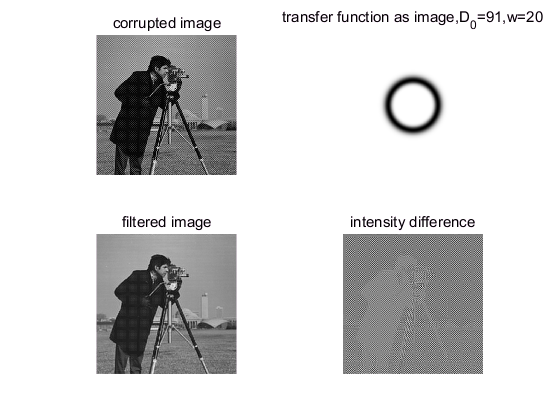

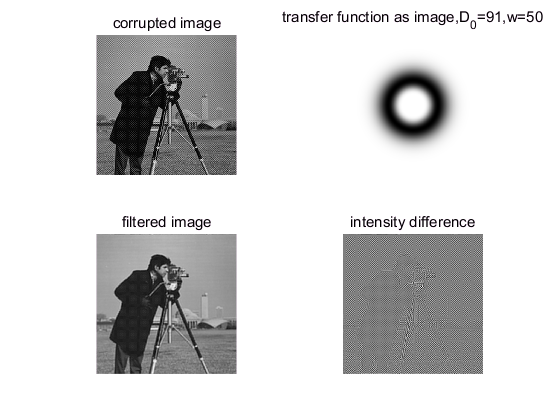

w = [20 50];
for i=1:length(w)
    Z = H(U,V,D0,w(i));
    F_p = F.*Z;
    I = ifft2(F_p);
    decentered_I =(-1).^(X+Y).*real(I);
    A = mat2gray(decentered_I);
    B = mat2gray(im);
    diff_inten = A-B;
    figure;
    subplot(2,2,1)
    imshow(im,[]);
    title('corrupted image')
    subplot(2,2,2)
    imshow(Z,[]);
    title(sprintf('transfer function as image,D_0=%d,w=%d',D0,w(i)))
    subplot(2,2,3)
    imshow(A,[]);
    title('filtered image')
    subplot(2,2,4)
    imshow(diff_inten,[]);
    title('intensity difference')
end

# Local Functions

function [M,T,X] = AffineFactorization(x)
n = size(x,1);
m = size(x,3);
T = mean(x,1);
x_centered = x - repmat(T,n,1,1);
T = squeeze(T);
W = [];
for i=1:m
    W = [W;x_centered(:,:,i)'];
end
[U,D,V] = svd(W);
M = U(:,1:3)*D(1:3,1:3);
X = V(:,1:3);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Question 1, part c, bonus
%
% Affine factorization upgrade 
%
function [M,X]=Upgrade(Min,Xin)
myfunc = @(A) objective(A,Min);
A=lsqnonlin(myfunc,reshape(eye(3),[9,1]));
A=reshape(A,[3 3]);
H = [inv(A) zeros(3,1);zeros(1,3),1];
X = H*[Xin ones(size(Xin,1),1)]';
X = X';
T = getT(X(:,1:3),3);
X = (T*X')';
X = X(:,1:3);
M = 1/T(1,1)*Min*A;
end

function [out] = objective(A,M)
A = reshape(A,[3,3]);
m = size(M,1)/2;
out = 0;
for i=1:m
    out = out + (M((i-1)*2+1,:)*A*A'*M((i-1)*2+2,:)')^2+(M((i-1)*2+1,:)*A*A'*M((i-1)*2+1,:)'-M((i-1)*2+2,:)*A*A'*M((i-1)*2+2,:)')^2;
end
end

function T = getT(X,c)
% check input
if ((~ismatrix(X)) || (size(X, 2) ~= c) || (size(X, 1) == 0))
	error('Input incorrect.');
end
N = size(X,1);
mu = mean(X,1);
tmp = [];
for i=1:c
   tmp = [tmp X(:,i)-mu(i)];
end
stdev = norm(tmp);
if stdev > 0
    s = sqrt(c) / stdev;
else
    s = 1;
end
t = zeros(c,1);
for i=1:c
    t(i) = - s * mu(i);
end
% replace the next line with your own code
T = [s*eye(c) t;[zeros(1,c) 1]];
end % end function getT